close all;

angle_condition = 95.7221726498029;
z_1 = discrete_desired_poles(1)

z_1 =     957.989672782773e-003 + 41.0736282385645e-003i


zero_lead = 0.965;

theta_0 = atan2d(imag(z_1), real(z_1) - zero_lead)

theta_0 =     99.6857456544377e+000


theta_p = theta_0 - angle_condition

theta_p =     3.96357300463482e+000


pole_lead = real(z_1) - imag(z_1) / tand(theta_p)

pole_lead =     365.193637941578e-003



G_lead = zpk([zero_lead], [pole_lead], 1, T);

evalfr(G_p, z_1)

ans =     11.7378553132953e-003 + 117.139441369952e-003i


evalfr(G_lead, z_1)

ans =    -6.99148093470858e-003 + 69.7723859411339e-003i


K_lead = 1 / (abs(evalfr(G_p, z_1)) * abs(evalfr(G_lead, z_1)));

G_lead = K_lead * G_lead

G_lead =
 
  121.14 (z-0.965)
  ----------------
     (z-0.3652)
 
Sample time: 0.03 seconds
Discrete-time zero/pole/gain model.



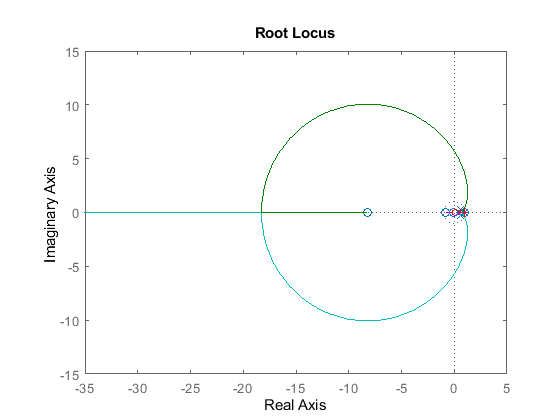


hold on;
rlocus(G_lead * G_p);
scatter(real(discrete_desired_poles), imag(discrete_desired_poles), 'r+');
hold off;

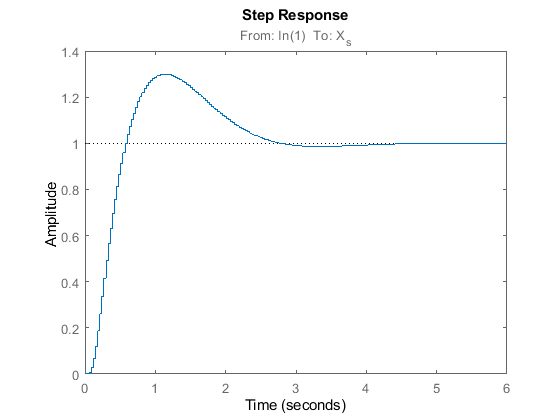


step(feedback(G_p * G_lead, 1))